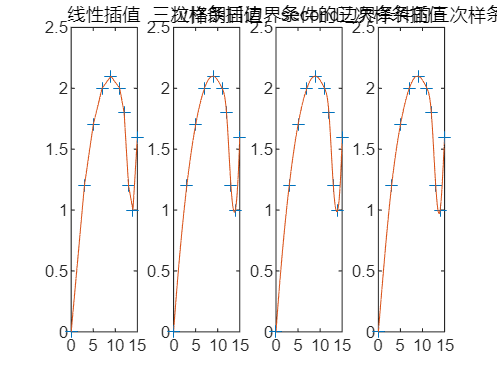

x0 = [0,3,5,7,9,11,12,13,14,15];
y0 = [0,1.2,1.7,2.0,2.1,2.0,1.8,1.2,1.0,1.6];
x = 0:0.1:15;
y1 = interp1(x0,y0,x);  %默认为线性插值
subplot(1,4,1);
plot(x0,y0,'+',x,y1)
title('线性插值');

y2 = interp1(x0,y0,x,'spline');  %三次样条插值
subplot(1,4,2);
plot(x0,y0,'+',x,y2);
title('三次样条插值');

%也是三次样条插值
pp1 = csape(x0,y0);  %默认为拉格朗日边界条件
y3 = fnval(pp1,x);
subplot(1,4,3);
plot(x0,y0,'+',x,y3);
title('拉格朗日边界条件的三次样条插值');

pp2 = csape(x0,y0,'second');  %边界条件选'second'
y4 = fnval(pp2,x);
subplot(1,4,4);
plot(x0,y0,'+',x,y4);
title('second边界条件的三次样条插值');


dx = diff(x);
dy = diff(y3);
dy_dx = dy./dx;
dy_dx0 =dy_dx(1)

dy_dx0 = 0.4972


ytemp = y3(131:151);
ymin = min(ytemp);
index = find(y3==ymin);
xmin = x(index);
xmin,ymin

xmin = 13.8000

ymin = 0.9851